## Read

data = readmatrix('0119-6cells.dat');
x = data(:,1);
y = data(:,2);
z = data(:,3);
clear data

## Show

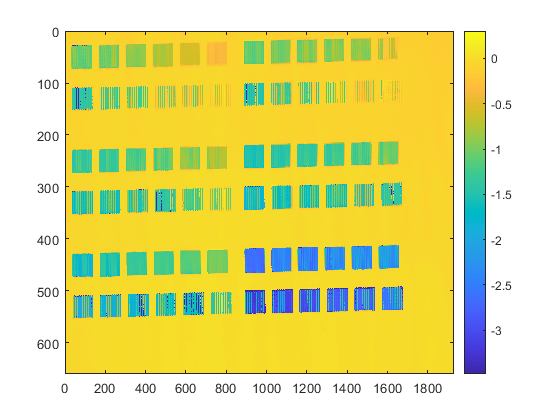

x_len = find(diff(y)~=0,1,"first");
y_len = floor(length(y)/x_len);
X = reshape(x,x_len,y_len);
Y = reshape(y,x_len,y_len);
Z = reshape(z,x_len,y_len);
x_range = [min(x),max(x)];
y_range = [min(y),max(y)];
figure
imagesc(x_range,y_range,Z')
colorbar

title('Raw')

## Rotate

Z_rot = imrotate(Z,0.5,'bilinear','crop');
imagesc(x_range,y_range,Z_rot')
colorbar
title('Rotated')
xlabel('um');ylabel('um')

## Get Aera of Interest central points

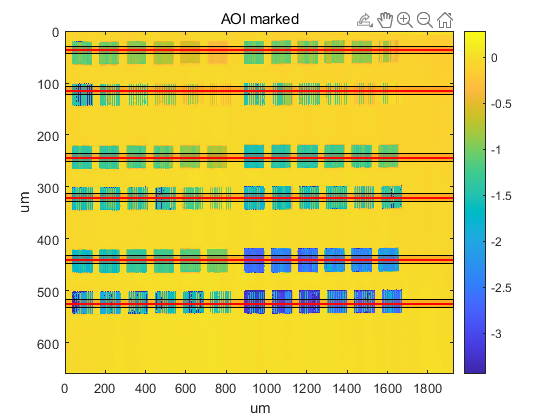

% width in um to avg.
width_of_AOI = 15;
% number of AOIs
num_of_AOI = 6;

[x_put,y_put] = ginput(num_of_AOI);
hold on
for ii=1:length(y_put)
    line(xlim,y_put(ii)*[1 1],'linewidth',1.5,'color','r')
    hold on
    dim = [min(x_range),y_put(ii)+width_of_AOI/2,diff(x_range),-width_of_AOI];
    dim_fig = dsxy2figxy(gca,dim);
    annotation('rectangle',dim_fig,...
        'FaceColor','red','FaceAlpha',.2)
end
hold off
title('AOI marked')

## 1D slice show of AOIs

figure
t = tiledlayout(length(y_put),1,"TileSpacing","compact");
dy = Y(1,2)-Y(1,1);
dx = X(2,1)-X(1,1);
z_slice = cell(1,length(y_put));
x_slice = cell(1,length(y_put));
for ii=1:length(y_put)
    nexttile
    y_ind = round([y_put(ii)-width_of_AOI/2, y_put(ii)+width_of_AOI/2]/dy);
    z_slice{ii} = mean(Z(:,y_ind),2);
    x_slice{ii} = X(:,1);
    plot(x_slice{ii},z_slice{ii})
end

## Show dubble-clipped version

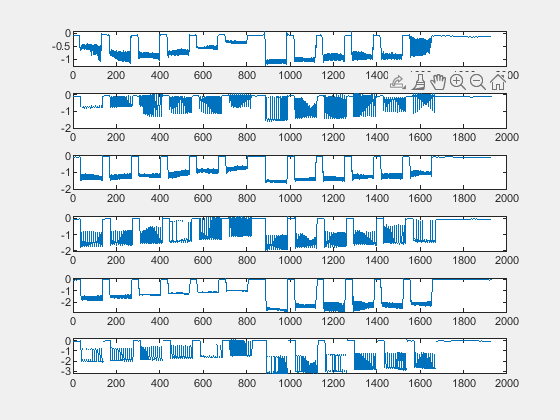

% get clip point
[x_put,~] = ginput(1);

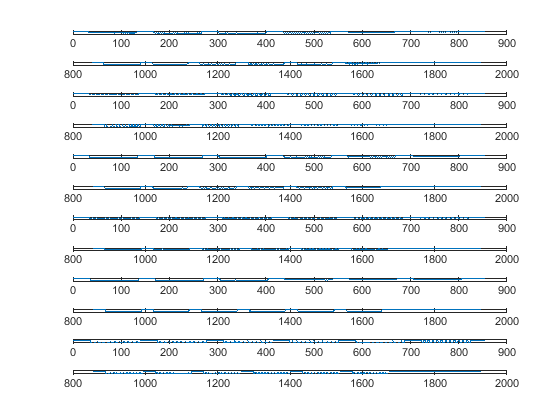


figure
t = tiledlayout(length(y_put)*2,1,"TileSpacing","compact");
for ii=1:length(y_put)
    x_clip_ind = round(x_put/dx);
    nexttile
    plot(x_slice{ii}(1:x_clip_ind),z_slice{ii}(1:x_clip_ind))
    nexttile
    plot(x_slice{ii}(x_clip_ind:end),z_slice{ii}(x_clip_ind:end))
end